% készítette: Barányi István
clear all;
close all;
r=[10 10 10;0 0 10;0 10 10; 10 0 0];
F=[0 0 -8; 8 0 0 ; 7 0 -7; -5 0 5];
Fe=sum(F)

Fe =     10     0   -10


[m,n]=size(r);
for i=1:m
    Me(i,:)=cross(r(i,:),F(i,:));
    
end
Me=sum(Me)

Me =   -150   180   -70


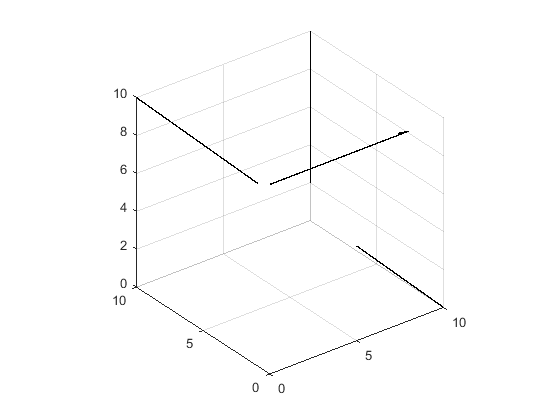

quiver3(r(1,1),r(1,2),r(1,3),F(1,1),F(1,2),F(1,3),0,'LineWidth',1,'color','black')
hold on
axis equal
xlim([0 10]);
ylim([0 10]);
zlim([0 10]);
for i=2:m
    quiver3(r(i,1),r(i,2),r(i,3),F(i,1),F(i,2),F(i,3),0,'LineWidth',1,'color','black')
    
end